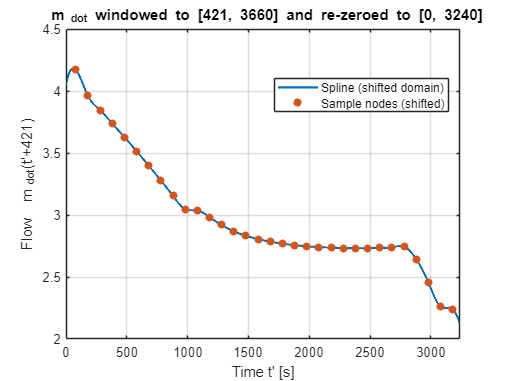

%% Plot \dot{m}(t) windowed to original [421, 3660] and re-zeroed to [0, 3240]
% Run the whole script so MATLAB registers the local function below.

t0 = linspace(0, 3240, 2001);        % new domain
f0 = dot_m_0to3240(t0);

figure
plot(t0, f0, 'LineWidth', 1.6); grid on
xlabel('Time t'' [s]'); ylabel('Flow \it m_{\it dot}(t''+421)');
title('\it m_{\it dot} windowed to [421, 3660] and re-zeroed to [0, 3240]')
xlim([0 3240])

% Overlay shifted original 100-s sample nodes
tn_all   = 1:100:4500;                % original node times (1..4401)
mask     = (tn_all >= 421) & (tn_all <= 3660);
tn_shift = tn_all(mask) - 421;        % now 0..3240
fn_shift = dot_m_0to3240(tn_shift);

hold on
scatter(tn_shift, fn_shift, 35, 'filled')
xline(0,'--'); xline(3240,'--');
legend('Spline (shifted domain)','Sample nodes (shifted)','Location','best')



%% Local function (keeps your data/code; evaluates at t = t' + 421, domain 0..3240)

function flow = dot_m_0to3240(tprime)
    % Original samples (kept as-is)
    power_values = [0.904165131160427, 1.62335959482857, 1.97415345554372, ...
                    2.87737856692485, 3.93386755649844, 4.17049006426838, ...
                    3.96224826445125, 3.84633136696794, 3.73843209854831, ...
                    3.62816620139765, 3.51470105395037, 3.39795514134232, ...
                    3.27785630468602, 3.15345777233773, 3.04616198439548, ...
                    3.03635175832522, 2.98312074354866, 2.91947217209040, ...
                    2.86878591164222, 2.83212849923799, 2.80518126603719, ...
                    2.78469068203536, 2.76888505493890, 2.75675815114367, ...
                    2.74763217287481, 2.74096591488524, 2.73636304275517, ...
                    2.73354386559958, 2.73235420493226, 2.73274273164412, ...
                    2.73475441155951, 2.73847704472223, 2.74398498698495, ...
                    2.64313697414983, 2.45549965647436, 2.26040185709996, ...
                    2.23930438794837, 1.99924539905101, 1.61176185199414, ...
                    1.31895743051123, 1.30916014023536, 1.07782805041202, ...
                    0.848496416787671, 0.620762639063214, -5.77778983316171e-34];

    % Original time stamps (kept as-is)
    time_vector = 1:100:4500;

    % New-domain guard
    if any(tprime(:) < 0 | tprime(:) > 3240)
        error('t'' must be within 0 to 3240 seconds.');
    end

    % Interpolate with the original spline, evaluated at shifted time t = t' + 421
    spline_fit = spline(time_vector, power_values);
    flow = ppval(spline_fit, tprime + 421);
end